# Predicting Player Position

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Load data

Load the basketball player statistics (per minute) data set.

data = readtable("./data/bballTrainingData.xlsx", Sheet="data");
dataTrain = readtable("./data/bballTrainingData.xlsx", Sheet="dataTrain");
dataTest = readtable("./data/bballTrainingData.xlsx", Sheet="dataTest");
whos

  Name             Size             Bytes  Class    Attributes

  data           609x22            317315  table              
  dataTest       182x20             52385  table              
  dataTrain      427x20            115879  table              



## Train kNN model

By default, `fitcknn` fits a kNN model with *k* = 1. That is, the model uses the class of the single closest "neighbor" to classify a new observation.

The model's performance may improve if the value of *k* is increased – that is, it uses the most common class of several neighbors, instead of just one.

You can change the value of *k* by setting the `"NumNeighbors"` property when calling `fitcknn`.

`mdl` `=` `fitcknn``(``table``,``"ResponseVariable"``,` `...`

    `"NumNeighbors"``,``7``)`

Using 5 nearest neighbors reduced the loss, but the model still misclassifies over 50% of the test data set.

Many machine learning methods use the distance between observations as a similarity measure. Smaller distances indicate more similar observations.

In the basketball data set, the statistics have different units and scales, which means some statistics will contribute more than others to the distance calculation. Centering and scaling each statistic makes them contribute more evenly.

By setting the `"Standardize"` property to `true` in the `fitcknn` function, each column of predictor data is normalized to have mean 0 and standard deviation 1, then the model is trained using the standardized data.

Fit a kNN classification model to the training data.

knnmodel = fitcknn(dataTrain, "pos", "NumNeighbors", 5, "Standardize", true);

## Evaluate model

Calculate misclassification rate.

mdlLoss = loss(knnmodel, dataTest)

mdlLoss = 0.3746

Display a confusion chart.

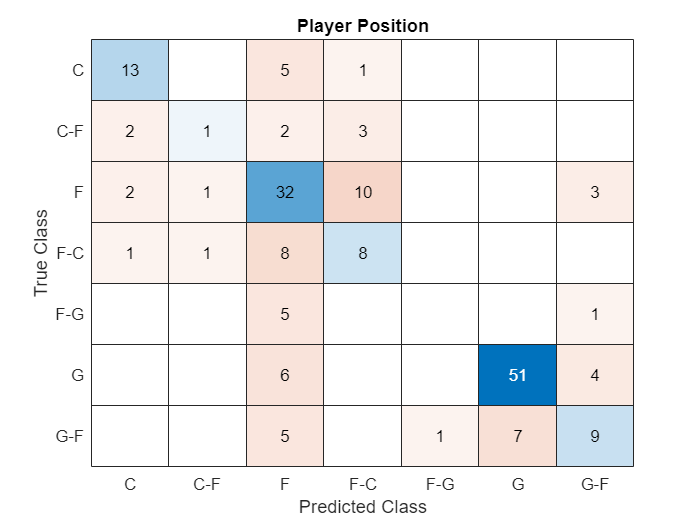

predPos = predict(knnmodel, dataTest);
confusionchart(dataTest.pos, predPos);
title("Player Position")